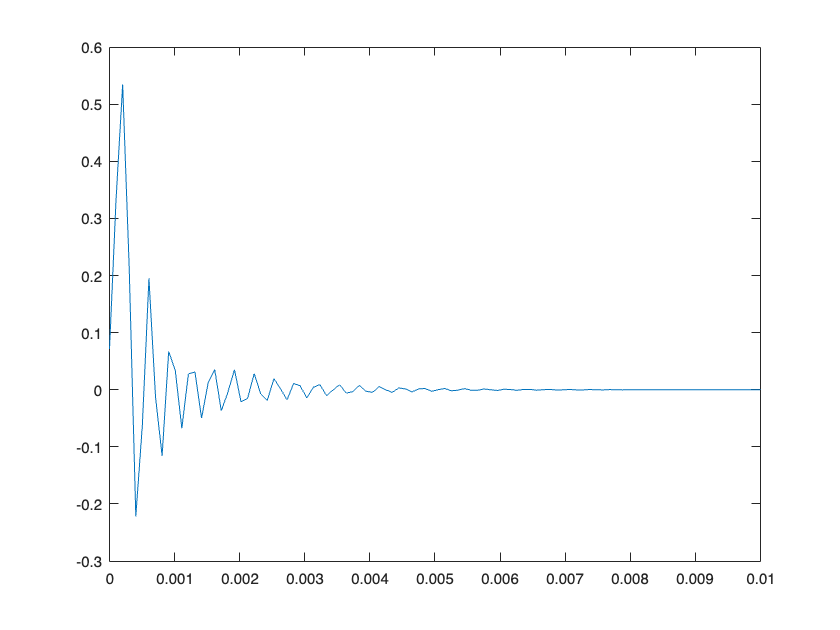

fc = 100e3;
fs = 1e6;
rp = 1;
% x: input signal
% y: filtered output signal

% Calculate analog cutoff frequency and convert to digital
wc = 2*pi*fc; % analog cutoff frequency
wd = 2*pi*fc/fs; % digital cutoff frequency

% Design Chebyshev Type I filter coefficients
[n, Wn] = cheb1ord(wd, 0.5*wd, rp, 60);
[b, a] = cheby1(n, rp, Wn);


L = 1e-2;
N_L = 100;
t = linspace(0, L, N_L); % delta function
x = [1, zeros(1, N_L-1)];

% Filter input signal using the filter coefficients
y = filter(b, a, x);
% Calculate frequency response
[H, w] = freqz(b, a, N_L);

figure
plot(t, y)

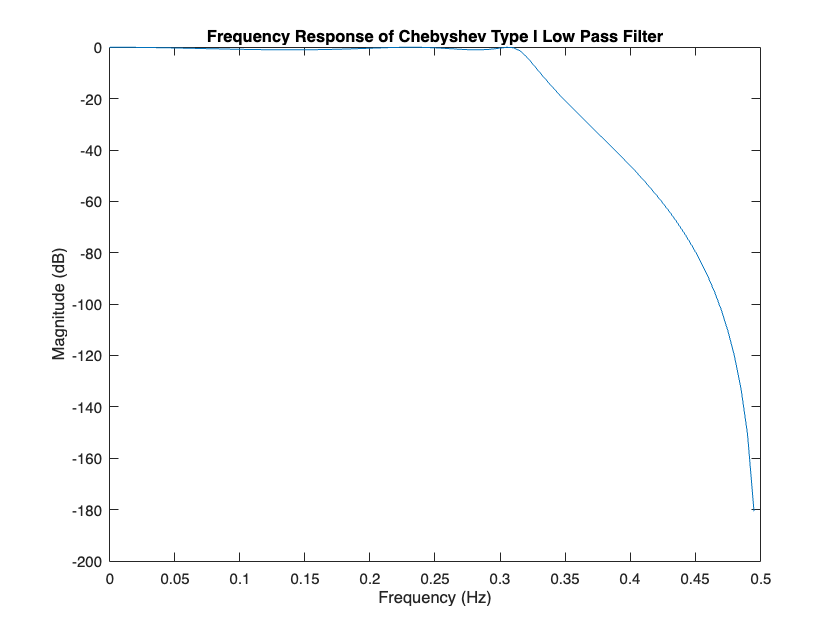


% Plot frequency response
figure;
plot(w/(2*pi), 20*log10(abs(H)));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency Response of Chebyshev Type I Low Pass Filter');